# Preprocess Ground Truth

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads a table containing filenames and corresponding bounding boxes.

load ../data/PetsImages/petGroundTruth.mat
petGroundTruth

petGroundTruth = 497×6 table
                     imageFilename                           Bengal              Chihuahua               Pug                 Samoyed               Sphynx      
    ________________________________________________    _________________    _________________    __________________    _________________    __________________

    "../data/PetsImages/Samoyed/Samoyed_175.jpg"        {0×0 double     }    {0×0 double     }    {0×0 double      }    {[215 70 72 116]}    {0×0 double      }
    "../data/PetsImages/Sphynx/Sphynx_201.jpg"          {0×0 double     }    {0×0 double     }    {0×0 double      }    {0×0 double     }    {[ 150 2 179 205]}
    "../data/PetsImages/Bengal/Bengal_135.jpg"          {[  18 17 53 63]}    {0×0 double     }    {0×0 double      }    {0×0 d

## Task 1

imds = imageDatastore(petGroundTruth.imageFilename)

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Deep_Learning_with_MATLAB\data\PetsImages\Samoyed\Samoyed_175.jpg';
                              ' ...\Deep_Learning_with_MATLAB\data\PetsImages\Sphynx\Sphynx_201.jpg';
                              ' ...\Deep_Learning_with_MATLAB\data\PetsImages\Bengal\Bengal_135.jpg'
                               ... and 494 more
                              }
                     Folders: {
                              ' ...\MATLAB_Courses\Deep_Learning_with_MATLAB\data\PetsImages\Samoyed';
                              ' ...\MATLAB_Courses\Deep_Learning_with_MATLAB\data\PetsImages\Sphynx';
                              ' ...\MATLAB_Courses\Deep_Learning_with_MATLAB\data\PetsImages\Bengal'
                               ... and 2 more
                              }
    AlternateFileSystemRoots: {}

## Task 2

The `boxLabelDatastore` function creates a datastore for bounding box label data.

`ds` `=` `boxLabelDatastore``(``tbl``)`

`tbl` is a table containing your bounding boxes. Each column represents an object class.

bxds = boxLabelDatastore(petGroundTruth(:, 2:end))

bxds =   boxLabelDatastore with properties:

    LabelData: 
               497x2 cell array
               
               {[215 70 72 116]}    {[Samoyed]}
               {[150 2 179 205]}    {[Sphynx ]}
               {[  18 17 53 63]}    {[Bengal ]}
               
                ... and 494 more rows
    ReadSize: 1


## Task 3

Your images and bounding boxes are now stored in two separate datastores. To process both datastores together, you need to combine them.

`dsnew` `=` `combine``(``ds1``,``ds2``)`

The first input should be the image datastore, and the second input should be the box label datastore.

data = combine(imds, bxds)

data =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 matlab.io.datastore.ImageDatastore]  [1×1 boxLabelDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]


## Task 4

The training images in this example vary in size. If you resize the images, you also need to resize the corresponding bounding boxes.

The `transform` function can preprocess existing datastores.

`dataout` `=` `transform``(``datain``,@``myfun``)`

`@``myfun` is a function handle to your preprocessing function. You will use the `scaleGT` function, which is located at the bottom of the script. It resizes images and bounding boxes using the same scale.

scaledData = transform(data, @scaleGT)

scaledData =   TransformedDatastore with properties:

      UnderlyingDatastores: {matlab.io.datastore.CombinedDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
                Transforms: {@scaleGT}
               IncludeInfo: 0


## Task 5

To view a preprocessed ground truth, you can preview the first image in the datastore.

`p` `=` `preview``(``ds``)`

newGT = preview(scaledData)

newGT = 1×3 cell array
    {224×224×3 uint8}    {[96.3200 46.9461 32.2560 77.7964]}    {[Samoyed]}


## Task 6

The result is a cell array with three elements:

- Scaled image

- Scaled bounding box

- Label

To view the result, you can annotate the scaled image.

`alteredImg` `=` `insertObjectAnnotation``(``image``,``...`

`"rectangle"``,``bbox``,``label``)`

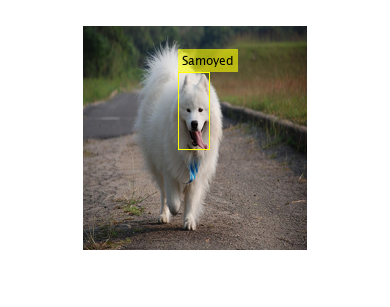

im = insertObjectAnnotation(newGT{1}, "rectangle", newGT{2}, newGT{3});
imshow(im)

`scaleGT` resizes images to `targetSize`. It also uses the same scale to resize the corresponding bounding boxes.

function data = scaleGT(data)  
    targetSize = [224 224];
    % data{1} is the image
    scale = targetSize./size(data{1}, [1 2]);
    data{1} = imresize(data{1}, targetSize);
    % data{2} is the bounding box
    data{2} = bboxresize(data{2}, scale);
end